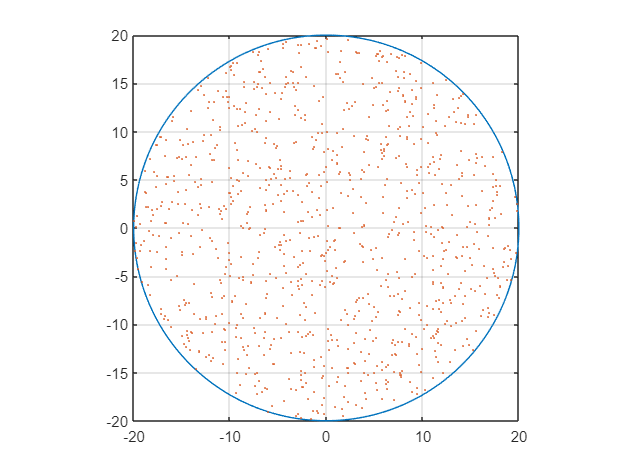

% Define the Boundary Area
% Equation of a circle given by: x^2 + y^2 = r^2
r = 20;                      % Radius of 2metres
k = 0;                      % Centre of circle is at (0,0)
for theta = 0:pi/300:2*pi   % Angle increment of 0.01
    k = k+1;
    xr(k) = r*cos(theta);
    yr(k) = r*sin(theta);
end
figure; 
plot(xr,yr);  hold on                % Plots a circle of radius 'r'
% Create a random set of coordinates in a circle.
% First define parameters that define the number of points and the circle.
n = 1000;
R = 20;
x0 = 0; % Center of the circle in the x direction.
y0 = 0; % Center of the circle in the y direction.
% Now create the set of points.
t = 2*pi*rand(n,1);
r = R*sqrt(rand(n,1));
x = x0 + r.*cos(t);
y = y0 + r.*sin(t);
% Now display our random set of points in a figure.
plot(x,y, 's', 'MarkerSize', 1); hold off
axis square;
grid on;